**LEP 5-4 : Pressure drop in a packed reactor**

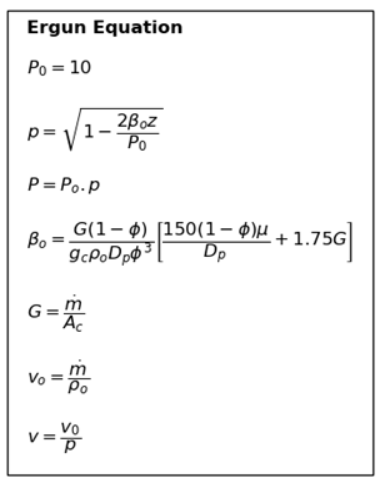

m=104.4;
Ac=0.01414;
viscosity=0.0673;
rho=0.413;
Dp=0.0208;
phi=0.45;
G = m/Ac;
gc = 4.17*10^8;
vo = m/rho;
P0 = 10;
z=linspace(0,100,100);
x=size(z);
for i=1:x(1,2)
Beta0 = (G* (1 -phi)* ((150 *(1 - phi)* viscosity/Dp)+ 1.75* G)/(gc*rho*Dp* (phi).^3))/(144*14.7);
p(i)= (1 - 2*Beta0* z(i)/P0).^0.5;
v(i) = vo/p(i);
P(i)= P0*p(i);
end
tiledlayout(1,2)
set (gcf,'Position',[0,0.1,800,400])
nexttile
plot(z,P,'LineWidth',2)

xlabel('z(ft)')
ylabel('P(atm)')
leg=legend('P');
leg.ItemTokenSize=[10,10];
axis([0 100 0 10])
title('Pressure profile')
grid on
nexttile
plot(z,v,'LineWidth',2)

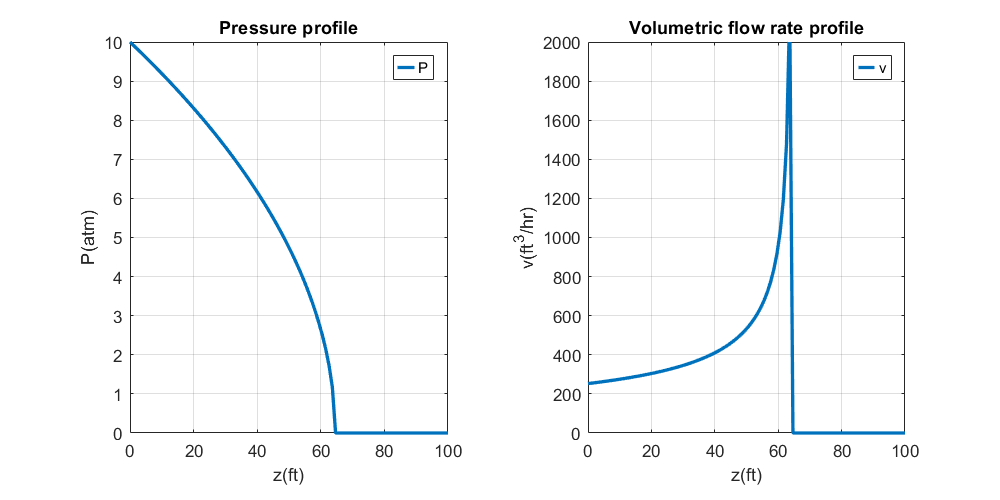

xlabel('z(ft)')
ylabel('v(ft^3/hr)')
leg=legend('v');
leg.ItemTokenSize=[10,10];
axis([0 100 0 2000])
title('Volumetric flow rate profile')
grid on